clc, clear all, close all

# Laboratorio 3 - Modelo diferencial de primer orden

#### Camilo Ernesto Campo Pacheco - Nicolas Pulido Gerena - Manuel Alejandro Rojas Cubillos

El repositorio de Github lo pueden encontrar en el siguiente [Link](https://github.com/npulidog/lab_3_robotica-2021II)

El siguiente documento muestra el trabajo realizado para el Laboratorio 3 de la materia Robótica donde se busca entender y simular el modelo diferencial de primer orden de un robot industrial asignado teniendo en cuenta sus características.

Para este laboratorio se tiene ya planteado desde laboratorios anteriores el analisis geometrico del robot **YUANDA **(Robot articulado y colaborativo de 6 ejes).

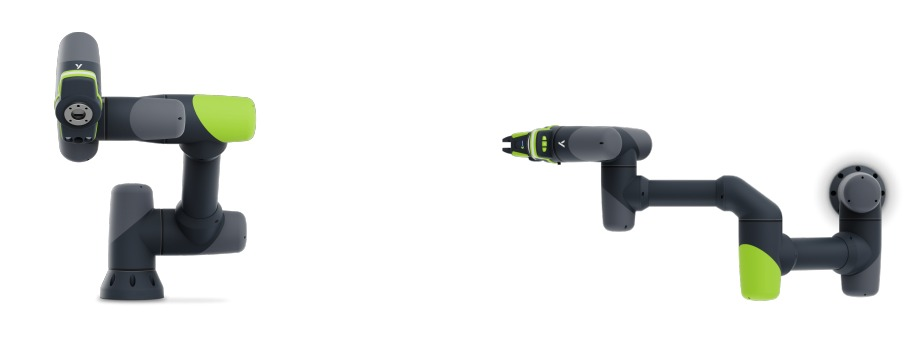

Robot Yuanda

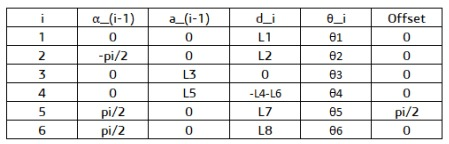

Tabla de parametros DHmod

### Modelo diferencial de primer Orden

**Considerando que para que el robot ejecute los movimientos, se desea establecer una relaci´on entre las velocidades del efector final y las articulaciones.**

**1.Con los valores numéricos de longitudes y desplazamientos de los eslabones del robot asignado obtenga el Jacobiano (como una matriz de valores numéricos, NO simbólicos) en función de los ángulos de articulación. **

A partir de la tabla de parametros DHmod se utilizan los parametros de DH estandar de la siguiente forma:

L1=5; L2=5; L3=30; L4=5; L5=45; L6=5; L7=5; L8=10; %Dimensiones en cm
ws = [-600 1000 -1000 1000 -1000 1000]/10;

plot_options = {'workspace',ws,'scale',.5,'view',[-5 25], 'tilesize',2,  'ortho', 'lightpos',[2 2 10], 'noa', 'base', 'basewidth', 10, 'trail', '*'};
 
L(1) = Link('revolute'   ,'alpha',    0,    'a',  0,   'd',    L1,      'offset',     0,    'qlim',  [-47*pi/120 47*pi/120],   'modified');
L(2) = Link('revolute'   ,'alpha',    -pi/2,'a',  0,   'd',    L2,      'offset',     0,    'qlim',  [-47*pi/120 47*pi/120],   'modified');
L(3) = Link('revolute'   ,'alpha',    0,    'a',  L3,  'd',    0,       'offset',     0,    'qlim',  [-169*pi/360 169*pi/360],   'modified');
L(4) = Link('revolute'   ,'alpha',    0,    'a',  L5,  'd',    -L4-L6 , 'offset',     0,    'qlim',  [-pi/2 pi/2],   'modified');
L(5) = Link('revolute'   ,'alpha',    pi/2, 'a',  0,   'd',    L7,      'offset',     pi/2, 'qlim',  [-pi/2 pi/2],   'modified');
L(6) = Link('revolute'   ,'alpha',    pi/2, 'a',  0,   'd',    L8,      'offset',     0,    'qlim',  [-pi/2 pi/2],   'modified');

Robot = SerialLink(L,'name','YUANDA','plotopt',plot_options) 

 
Robot = 
 
YUANDA (6 axis, RRRRRR, modDH, fastRNE)                          
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          5|          0|          0|          0|
|  2|         q2|          5|          0|     -1.571|          0|
|  3|         q3|          0|         30|          0|          0|
|  4|         q4|        -10|         45|          0|          0|
|  5|         q5|          5|          0|      1.571|      1.571|
|  6|         q6|         10|          0|      1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0            


q = [-47*pi/120 0 0 -pi/2 -pi/2 0];

A_0_1 = L(1).A(q(1))

A_0_1 =     0.3338    0.9426         0         0
   -0.9426    0.3338         0         0
         0         0    1.0000    5.0000
         0         0         0    1.0000


A_1_2 = L(2).A(q(2))

A_1_2 =     1.0000         0         0         0
         0    0.0000    1.0000    5.0000
         0   -1.0000    0.0000    0.0000
         0         0         0    1.0000


A_2_3 = L(3).A(q(3))

A_2_3 =      1     0     0    30
     0     1     0     0
     0     0     1     0
     0     0     0     1


A_3_4 = L(4).A(q(4))

A_3_4 =     0.0000    1.0000         0   45.0000
   -1.0000    0.0000         0         0
         0         0    1.0000  -10.0000
         0         0         0    1.0000


A_4_5 = L(5).A(q(5))

A_4_5 =     1.0000         0         0         0
         0    0.0000   -1.0000   -5.0000
         0    1.0000    0.0000    0.0000
         0         0         0    1.0000


A_5_6 = L(6).A(q(6))

A_5_6 =     1.0000         0         0         0
         0    0.0000   -1.0000  -10.0000
         0    1.0000    0.0000    0.0000
         0         0         0    1.0000



T_0_1 = A_0_1 * eye(4)

T_0_1 =     0.3338    0.9426         0         0
   -0.9426    0.3338         0         0
         0         0    1.0000    5.0000
         0         0         0    1.0000


T_0_2 = A_0_1 * A_1_2 * eye(4)

T_0_2 =     0.3338    0.0000    0.9426    4.7132
   -0.9426    0.0000    0.3338    1.6690
         0   -1.0000    0.0000    5.0000
         0         0         0    1.0000


T_0_3 = A_0_1 * A_1_2 * A_2_3 * eye(4)

T_0_3 =     0.3338    0.0000    0.9426   14.7274
   -0.9426    0.0000    0.3338  -26.6102
         0   -1.0000    0.0000    5.0000
         0         0         0    1.0000


T_0_4 = A_0_1 * A_1_2 * A_2_3 * A_3_4 * eye(4)

T_0_4 =    -0.0000    0.3338    0.9426   20.3223
   -0.0000   -0.9426    0.3338  -72.3671
    1.0000   -0.0000    0.0000    5.0000
         0         0         0    1.0000


T_0_5 = A_0_1 * A_1_2 * A_2_3 * A_3_4 * A_4_5 * eye(4)

T_0_5 =    -0.0000    0.9426   -0.3338   18.6533
   -0.0000    0.3338    0.9426  -67.6539
    1.0000    0.0000    0.0000    5.0000
         0         0         0    1.0000


T_0_6 = A_0_1 * A_1_2 * A_2_3 * A_3_4 * A_4_5 * A_5_6 * eye(4)

T_0_6 =    -0.0000   -0.3338   -0.9426    9.2269
   -0.0000    0.9426   -0.3338  -70.9920
    1.0000    0.0000   -0.0000    5.0000
         0         0         0    1.0000



Z_0 = [0; 0; 1]

Z_0 =      0
     0
     1


Z_1 = [T_0_1(1,3); T_0_1(2,3); T_0_1(3,3)]

Z_1 =      0
     0
     1


Z_2 = [T_0_2(1,3); T_0_2(2,3); T_0_2(3,3)]

Z_2 =     0.9426
    0.3338
    0.0000


Z_3 = [T_0_3(1,3); T_0_3(2,3); T_0_3(3,3)]

Z_3 =     0.9426
    0.3338
    0.0000


Z_4 = [T_0_4(1,3); T_0_4(2,3); T_0_4(3,3)]

Z_4 =     0.9426
    0.3338
    0.0000


Z_5 = [T_0_5(1,3); T_0_5(2,3); T_0_5(3,3)]

Z_5 =    -0.3338
    0.9426
    0.0000




T_0 = [0; 0; 0]

T_0 =      0
     0
     0


T_1 = [T_0_1(1,4); T_0_1(2,4); T_0_1(3,4)]

T_1 =      0
     0
     5


T_2 = [T_0_2(1,4); T_0_2(2,4); T_0_2(3,4)]

T_2 =     4.7132
    1.6690
    5.0000


T_3 = [T_0_3(1,4); T_0_3(2,4); T_0_3(3,4)]

T_3 =    14.7274
  -26.6102
    5.0000


T_4 = [T_0_4(1,4); T_0_4(2,4); T_0_4(3,4)]

T_4 =    20.3223
  -72.3671
    5.0000


T_5 = [T_0_5(1,4); T_0_5(2,4); T_0_5(3,4)]

T_5 =    18.6533
  -67.6539
    5.0000


T_6 = [T_0_6(1,4); T_0_6(2,4); T_0_6(3,4)]

T_6 =     9.2269
  -70.9920
    5.0000



J = [cross(Z_0,(T_6-T_0)) cross(Z_1,(T_6-T_1)) cross(Z_2,(T_6-T_2))...
    cross(Z_3,(T_6-T_3)) cross(Z_4,(T_6-T_4)) cross(Z_5,(T_6-T_5));
    Z_0 Z_1 Z_2 Z_3 Z_4 Z_5]

J =    70.9920   70.9920    0.0000    0.0000   -0.0000   -0.0000
    9.2269    9.2269    0.0000    0.0000    0.0000   -0.0000
         0         0  -70.0000  -40.0000    5.0000   10.0000
         0         0    0.9426    0.9426    0.9426   -0.3338
         0         0    0.3338    0.3338    0.3338    0.9426
    1.0000    1.0000    0.0000    0.0000    0.0000    0.0000


El valor de "J" visto anteriormente, corresponde al Jacobiano.

**2. Para una postura de su elección dentro del espacio diestro del robot obtenga las velocidades de articulación para: **

Para el inverso del Jacobiano se utiliza el siguiente comando:

Jinv = pinv(J)

Jinv =     0.0069    0.0009    0.0000    0.0000    0.0000    0.0001
    0.0069    0.0009    0.0000    0.0000    0.0000    0.0001
   -0.0000    0.0000   -0.0123   -0.1320    0.0836    0.0000
    0.0000   -0.0000   -0.0018    0.2505    0.1073    0.0000
    0.0000   -0.0000    0.0140    0.8241    0.1429    0.0000
   -0.0000    0.0000    0.0000   -0.3338    0.9426    0.0000


Obteniendo asi:

V_H = [100;200;50]

V_H =    100
   200
    50


w_H = [5;10;-5]

w_H =      5
    10
    -5


vector = [V_H;w_H]

vector =    100
   200
    50
     5
    10
    -5


q_punto = Jinv*vector

q_punto =     0.8720
    0.8720
   -0.4383
    2.2378
    6.2518
    7.7574


### Integración

**Ahora con la ayuda de los algoritmos desarrollados y de la GUI construida. **

**1. Ubique la ruta seleccionada con la orientación indicada dentro del espacio diestro del robot.**

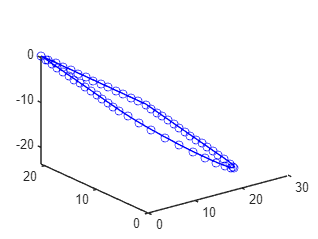

Horizontal = 85; %valor en cm
L = 0.4*Horizontal;

r = 0.3*L;
n = 15;

t1 = [linspace(0,L-r,n)' zeros(n,2)];
theta = linspace(-pi/2,pi/2, n);
cx = (L-r);
cy = r;
cz = 0;

t2 = [cx+r*cos(theta)' cy+r*sin(theta)' cz+0.*theta'];
t3 = [t2(end,:);linspace(L-r,0,n)' 2*r.*ones(n,1) zeros(n,1)];
t4 = [t3(end,:);zeros(n,1) linspace(2*r,0,n)' zeros(n,1)];

ruta = [t1; t2; t3; t4];

clf
R0_t = roty(45,'deg'); %%Definición del plano-vector [-1, 0, 1]
p0_t = [0 0.4 0.4];
ruta_ = 0.*ruta;
for i=1:length(ruta(:,1))
    ruta_(i,:) = R0_t*ruta(i,:)'+p0_t';
end

figure (1)
plot3(ruta_(:,1),ruta_(:,2),ruta_(:,3),'-bo')

**2. Calcule las configuraciones correspondientes a cada viapoint. Presente una gráfica de cada ángulo de articulación al recorrer la ruta.**

Se crea el robot utilizando RST:

robot = rigidBodyTree;
body1 = rigidBody('body1'); 
body2 = rigidBody('body2'); 
body3 = rigidBody('body3'); 
body4 = rigidBody('body4'); 
body5 = rigidBody('body5'); 
body6 = rigidBody('body6'); 
bodyEndEffector=rigidBody('endeffector');
jnt1 = rigidBodyJoint('jnt1','revolute');
jnt2 = rigidBodyJoint('jnt2','revolute');
jnt3 = rigidBodyJoint('jnt3','revolute');
jnt4 = rigidBodyJoint('jnt4','revolute');
jnt5 = rigidBodyJoint('jnt5','revolute');
jnt6 = rigidBodyJoint('jnt6','revolute');
%body1
tform1 = transl(0, 0, 5);
setFixedTransform(jnt1,tform1); 
body1.Joint = jnt1;
addBody(robot,body1,'base')

%body2
tform2 = transl(0, 0, 5)*troty(-pi/2);
setFixedTransform(jnt2,tform2);
body2.Joint = jnt2;
addBody(robot,body2,'body1')

%body3
tform3 = transl(0, 30, 0);
setFixedTransform(jnt3,tform3);
body3.Joint = jnt3;
addBody(robot,body3,'body2')

%body4
tform4 = transl(0, 45, -10);
setFixedTransform(jnt4,tform4);
body4.Joint = jnt4;
addBody(robot,body4,'body3')

%body5
tform5 = transl(0, 0, 5)*troty(pi/2)*trotz(-pi/2);
setFixedTransform(jnt5,tform5);
body5.Joint = jnt5;
addBody(robot,body5,'body4')

%body6
tform6 = transl(0, 0, 10)*troty(pi/2);
setFixedTransform(jnt6,tform6);
body6.Joint = jnt6;
addBody(robot,body6,'body5')

%endEffector
tform7 = trvec2tform([0 0 0]);
setFixedTransform(bodyEndEffector.Joint,tform7);
addBody(robot,bodyEndEffector,'body6')

Ahora se realiza la cinematica inversa:

ik = inverseKinematics('RigidBodyTree', robot);
weights = [0.25 0.25 0.25 1 1 1];
initialguess = homeConfiguration(robot);
robot.BodyNames

ans = 1×7 cell array
    {'body1'}    {'body2'}    {'body3'}    {'body4'}    {'body5'}    {'body6'}    {'endeffector'}



viapoints = length(ruta(:,1));
conf_ruta = zeros(viapoints,6);
for i=1:viapoints
    tic
    if i>1
        initialguess = configSoln;
    end
    p0_t = ruta_(i,:);
    R0_t = rotx(-135,'deg');
    MTHpose = [R0_t p0_t'; 0 0 0 1];
    [configSoln,solnInfo] = ik('endeffector',MTHpose,weights,initialguess);
    conf_ruta(i,:) = [configSoln(1).JointPosition configSoln(2).JointPosition configSoln(3).JointPosition ...
        configSoln(4).JointPosition configSoln(5).JointPosition configSoln(6).JointPosition];
    rutaxd(i,:) = configSoln';
    disp(strcat(num2str(i),"/",num2str(viapoints)))
    toc
end

1/62


Elapsed time is 7.876492 seconds.


2/62


Elapsed time is 4.644859 seconds.


3/62


Elapsed time is 5.196220 seconds.


4/62


Elapsed time is 4.868953 seconds.


5/62


Elapsed time is 4.598390 seconds.


6/62


Elapsed time is 0.167596 seconds.


7/62


Elapsed time is 0.197903 seconds.


8/62


Elapsed time is 0.150084 seconds.


9/62


Elapsed time is 0.260742 seconds.


10/62


Elapsed time is 0.192085 seconds.


11/62


Elapsed time is 0.240243 seconds.


12/62


Elapsed time is 0.295427 seconds.


13/62


Elapsed time is 0.145648 seconds.


14/62


Elapsed time is 0.167767 seconds.


15/62


Elapsed time is 0.177868 seconds.


16/62


Elapsed time is 0.031404 seconds.


17/62


Elapsed time is 0.182039 seconds.


18/62


Elapsed time is 0.218278 seconds.


19/62


Elapsed time is 0.182286 seconds.


20/62


Elapsed time is 0.158245 seconds.


21/62


Elapsed time is 0.177649 seconds.


22/62


Elapsed time is 0.189428 seconds.


23/62


Elapsed time is 0.204839 seconds.


24/62


Elapsed time is 0.236809 seconds.


25/62


Elapsed time is 0.240628 seconds.


26/62


Elapsed time is 0.215906 seconds.


27/62


Elapsed time is 0.304532 seconds.


28/62


Elapsed time is 0.228108 seconds.


29/62


Elapsed time is 0.214690 seconds.


30/62


Elapsed time is 0.203873 seconds.


31/62


Elapsed time is 0.218179 seconds.


32/62


Elapsed time is 0.188195 seconds.


33/62


Elapsed time is 0.198913 seconds.


34/62


Elapsed time is 0.178307 seconds.


35/62


Elapsed time is 0.205599 seconds.


36/62


Elapsed time is 0.193566 seconds.


37/62


Elapsed time is 0.226258 seconds.


38/62


Elapsed time is 0.171874 seconds.


39/62


Elapsed time is 0.186809 seconds.


40/62


Elapsed time is 0.193793 seconds.


41/62


Elapsed time is 0.179074 seconds.


42/62


Elapsed time is 0.196929 seconds.


43/62


Elapsed time is 0.187094 seconds.


44/62


Elapsed time is 0.200737 seconds.


45/62


Elapsed time is 0.173481 seconds.


46/62


Elapsed time is 0.266205 seconds.


47/62


Elapsed time is 0.032453 seconds.


48/62


Elapsed time is 0.015111 seconds.


49/62


Elapsed time is 0.318389 seconds.


50/62


Elapsed time is 0.281974 seconds.


51/62


Elapsed time is 0.361890 seconds.


52/62


Elapsed time is 0.272947 seconds.


53/62


Elapsed time is 0.302156 seconds.


54/62


Elapsed time is 0.188657 seconds.


55/62


Elapsed time is 0.264599 seconds.


56/62


Elapsed time is 0.254978 seconds.


57/62


Elapsed time is 1.777458 seconds.


58/62


Elapsed time is 0.252880 seconds.


59/62


Elapsed time is 6.963559 seconds.


60/62


Elapsed time is 5.805444 seconds.


61/62


Elapsed time is 6.241584 seconds.


62/62


Elapsed time is 7.095118 seconds.


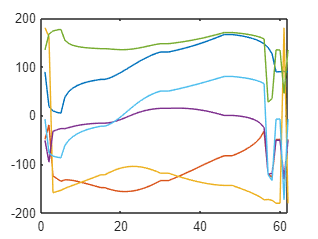


figure (2)
plot(conf_ruta(:,1)*180/pi)
hold on
plot(conf_ruta(:,2)*180/pi)
hold on
plot(conf_ruta(:,3)*180/pi)
hold on
plot(conf_ruta(:,4)*180/pi)
hold on
plot(conf_ruta(:,5)*180/pi)
hold on
plot(conf_ruta(:,6)*180/pi)
hold off

Para la velocidad fija en la trayectoria (500mm/s):

Jacobianos = cell(1,viapoints);
for i=1:viapoints
    Jacobianos{i} = geometricJacobian(robot,rutaxd(i,:),'endeffector');
end

tiempos = zeros(61,1);
distancia_tot = 0;
distancias = zeros(61,3); 
velocidad = 0.5;
for j=1:viapoints-1
    norma = norm(ruta_(j+1,:)-ruta_(j,:)); 
    distancia_tot = distancia_tot + norma;
    if norma ~= 0
        distancias(j,:) = (ruta_(j+1,:)-ruta_(j,:));
        tiempos(j) = norma/velocidad;
    else
        distancias(j,:) = [0 0 0];
    end
end

Para la velocidad lineal instantánea:

v = zeros(61,3);
for k=1:viapoints-1
    if(tiempos(k) ~= 0)
        v(k,:) = (distancias(k)/tiempos(k));
    else
        v(k,:) = [0 0 0];
    end
end
v = [[0 0 0]; v];
w = zeros(62,3);
vw = [v, w];
q_punto = zeros(6,62);

for i=1:viapoints
    q_punto(:,i) = inv(Jacobianos{i})*vw(i,:)';
end


t = zeros(62,1);
for i = 2 : viapoints
    t(i) = t(i-1) + tiempos(i-1);
end 

Graficando:

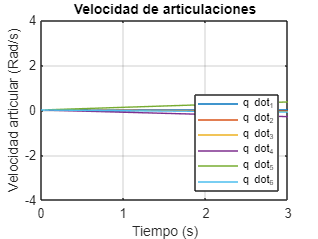

clf
for i=1:6
    plot(t,q_punto(i,:), 'DisplayName',['q dot_',num2str(i)])
    hold on
end
legend('Location',"southeast")
grid on
hold off
title('Velocidad de articulaciones')
xlim([0.00 3.00])
ylim([-4.00 4.00])
xlabel('Tiempo (s)')
ylabel('Velocidad articular (Rad/s)')

Para la animación del Robot, se utiliza el siguiente codigo en comentario para evitar errores de compilación (Se cuenta como anexo el video en Github donde se presenta la animación):

% fps=60;r=rateControl(fps);
% show(robot,rutaxd(1,:))
% ax=gca;
% hold on
% plot3(ax,ruta_(:,1),ruta_(:,2),ruta_(:,3),'-bo');
% hold on
% while true
% for i=1:viapoints
%     show(robot,rutaxd(i,:),'PreservePlot',false);
%     drawnow
%     waitfor(r);
% end
% end

El repositorio de Github lo pueden encontrar en el siguiente [Link](https://github.com/npulidog/lab_3_robotica-2021II)